clc
clear
%作者；暴富
%时间：2024-06-25
%项目：example2.3中单个分析方法2累加方法


%并行池的开和关
%parpool%开
%delete(gcp)%关

%%初始化
T = 0.01;
t = 0:T:15;
N = length(t);
X = zeros(6,N);%agent初始化
X_state = zeros(6,6,N);

lineStyles = linspecer(6); % 指定线型颜色,6个状态

%agengt状态初始化
X(1,1) = 1;
X(2,1) = -1;
X(3,1) = 3;
X(4,1) = -3;
X(5,1) = 5;
X(6,1) = -5;


%%图A的邻接矩阵
A_a = [ 0  1   1  0  0  0;...
           1  0   1  1  0  1;...
           1  1   0  0  1  0;...
           0  1   0  0  0  1;...
           0  0   1  0  0  1;...
           0  1   0  1  1  0];
    

%% 方程实现求和


$$$$
\sum_{j=1}^n{a_{ij}\left( x_j-x_i \right)}
$$
$$
 


$$sum\_term = sum\_term + a_{ij}(x_j-x_i)$$



%%迭代过程

for k = 2:N
    for ii = 1:6
        sum_term = 0;
        for jj = 1:6
            sum_term = sum_term + A_a(ii,jj) * (X(jj,k-1)-X(ii,k-1));
        end
        X(ii,k) =T*sum_term+X(ii,k-1);  
    end
end

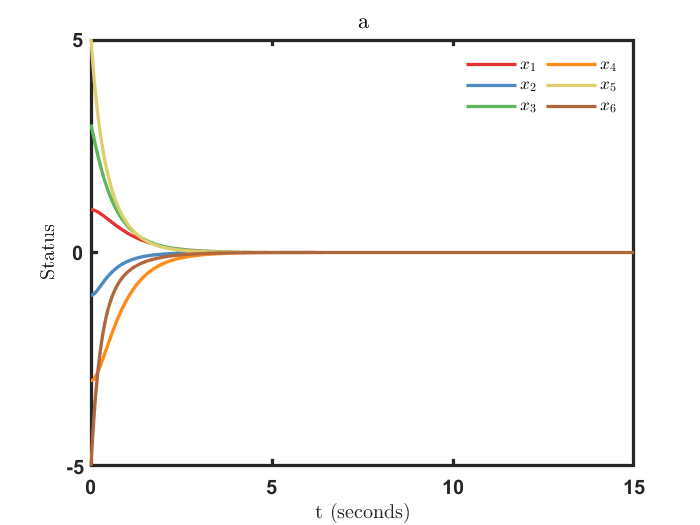

%% 绘制结果
hf = figure;  %新建 图形控制句柄
hf.Color= [1 1 1]; % 控制图形的整体颜色。（scope中被默认为灰黑色，此处修改为白色）
plot(t,X(1,:),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,X(2,:),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,X(3,:),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,X(4,:),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,X(5,:),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,X(6,:),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','a')